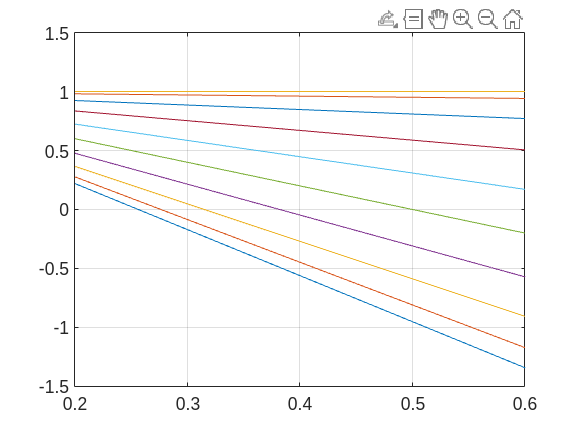

N = 10;
N_mu = 200;
mu = linspace(0.2,0.6,N_mu);
Eigs = zeros(N,N_mu);
for i = 1:N_mu
    Eigs(:,i) = eig(A_N(mu(i),N));
end

figure;
hold on, grid on, box on;
plot(mu,Eigs')

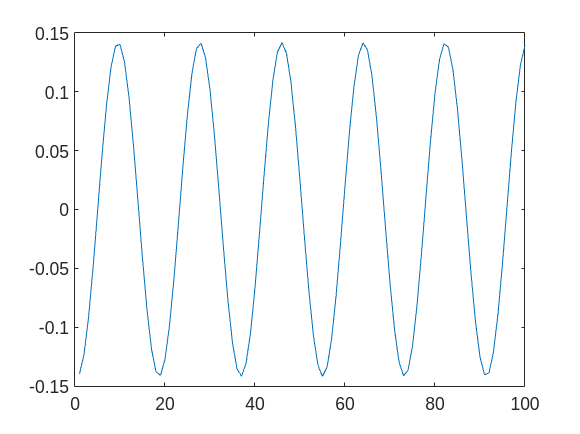

N = 100;
mu = 0.1;

A = A_N(mu,N);
[S,D] = eig(A);

figure,
plot(S(:,89))


1 - flip(eig(D))

ans =                    0
   0.000098687926854
   0.000394654314345
   0.000887607079384
   0.001577059737104
   0.002462331880972
   0.003542549854262
   0.004816647612250
   0.006283367774274
   0.007941262864611


function A = A_N(mu,N)
    a = [1-2*mu mu zeros(1,N-2)];
    A = toeplitz(a,a);
    A(1) = 1-mu;
    A(end) = 1-mu;
end